syms t
A=sym([-5 1; 4 -2])

$$A = \left(\begin{array}{cc} -5 & 1\\ 4 & -2 \end{array}\right)$$

[S,D]=eig(A)

$$S = \left(\begin{array}{cc} -1 & \frac{1}{4}\\ 1 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{cc} -6 & 0\\ 0 & -1 \end{array}\right)$$

b=[1 2]';
ts = linspace(-.4,1,100);
S*expm(D*t)*S^-1*b

$$ans = \left(\begin{array}{c} \frac{3\,{\mathrm{e}}^{-t}}{5}+\frac{2\,{\mathrm{e}}^{-6\,t}}{5}\\ \frac{12\,{\mathrm{e}}^{-t}}{5}-\frac{2\,{\mathrm{e}}^{-6\,t}}{5} \end{array}\right)$$

pt = @(t) S*expm(D*t)*S^-1*b

pt = function_handle with value:
    @(t)S*expm(D*t)*S^-1*b


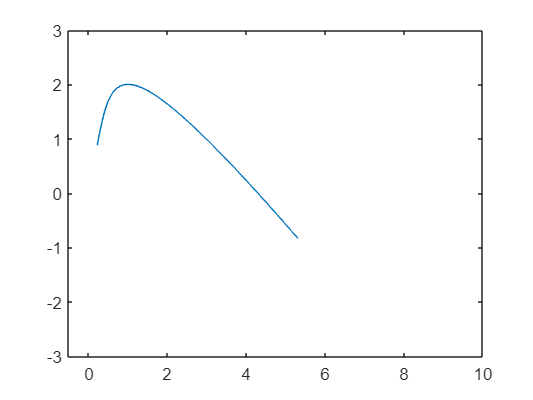

pts = zeros(2,100);
for i = 1:100
    pts(:,i) = pt(ts(i));
end
plot(pts(1,:),pts(2,:))
axis([-.5,10,-3,3])